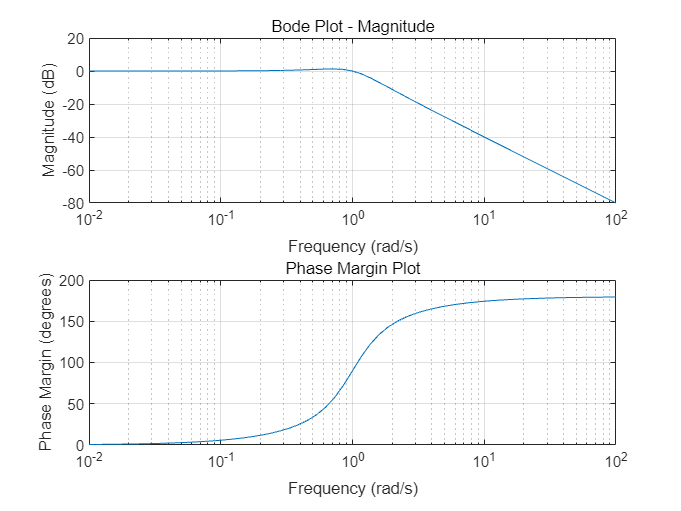

% 定义传递函数
num = [1];
den = [1, 1, 1];
sys = tf(num, den);

% 绘制Bode图
[mag, phase, wout] = bode(sys);

% 计算相位裕度
PM = zeros(size(mag, 3), 1);
for i = 1:size(mag, 3)
    [~, idx] = min(abs(phase(:, :, i) + 180));
    PM(i) = 180 - (phase(idx, 1, i) + 180);
end

figure;
subplot(2, 1, 1);
semilogx(wout, 20*log10(squeeze(mag)));
grid on;
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Bode Plot - Magnitude');

% 绘制相位裕度线条
subplot(2, 1, 2);
semilogx(wout, PM);
grid on;
xlabel('Frequency (rad/s)');
ylabel('Phase Margin (degrees)');
title('Phase Margin Plot');